# Model Interpretation

fpath = genpath("C:\Users\regen\Documents\MATLAB\functions");
dpath = genpath("C:\Users\regen\Documents\MATLAB\Stage 6 Regression Second Try\saved data");
addpath(fpath,dpath);
load 'Stage 6 Regression Second Try'\'saved data'\models\bestSubset.mat

Compute Shapley Values for the case of 6 sensors:

Tp14_tbl = bestSubset(6).Tp_14_sorted_fitted;
predFcn = bestSubset(6).Tp_model.predictFcn;
idx = bestSubset(6).combination;

shap = shapley(predFcn,Tp14_tbl(:,1:end-1),UseParallel=true)

shap =             BlackboxModel: @(x)linearModelPredictFcn(predictorExtractionFcn(x))
              QueryPoints: []
           BlackboxFitted: []
            ShapleyValues: []
                        X: [1378×14 table]
    CategoricalPredictors: []
                   Method: "interventional-kernel"
                Intercept: 42.2131
               NumSubsets: 1024


shap_val = fit(shap,Tp14_tbl(:,1:end-1),UseParallel=true)

Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 6 workers.


shap_val = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"         8.5356e-13 
    "187.5"       8.5134e-13 
    "195"             5.0659 
    "202.5"           7.2613 
    "210"             6.6628 
    "217.5"       8.2403e-13 
    "225"         8.2198e-13 
    "232.5"            9.067 
    "240"             12.033 
    "247.5"       8.1633e-13 
    "255"          8.195e-13 
    "262.5"           1.1411 
    "270"         8.1862e-13 
    "T_value"          1.807 


  Properties, Methods



% 理论上，swarmchart的前7个应该是T_value, 240, 232.5, 210, 202.5, 195, 262.5
% 毕竟其余的不参与预测

Rank feature importance based on mean absolute shapley values:

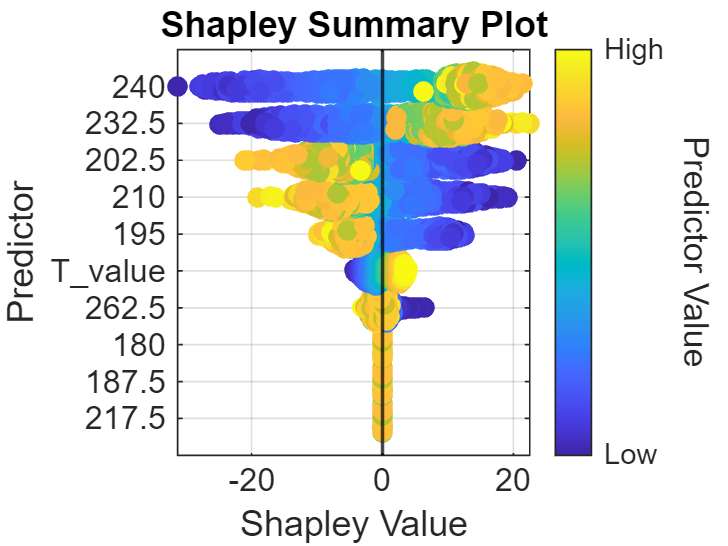

% swarmchart
figure, swarmchart(shap_val)

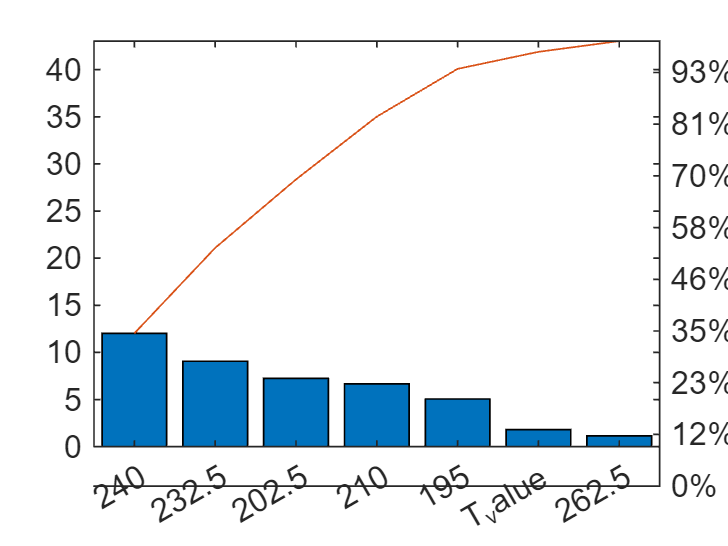


% pareto
figure, grid on
pareto(shap_val.MeanAbsoluteShapley{[idx,end],"ShapleyValue"},shap_val.MeanAbsoluteShapley{[idx,end],"Predictor"},1)

Compute Shapley values for various cases

1 senors, index: 9


Positions: 240


Starting parallel pool (parpool) using the 'Processes' profile ...
Preserving jobs with IDs: 1 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile Processes. To create 'myCluster' use 'myCluster = parcluster('Processes')'.
Connected to parallel pool with 6 workers.


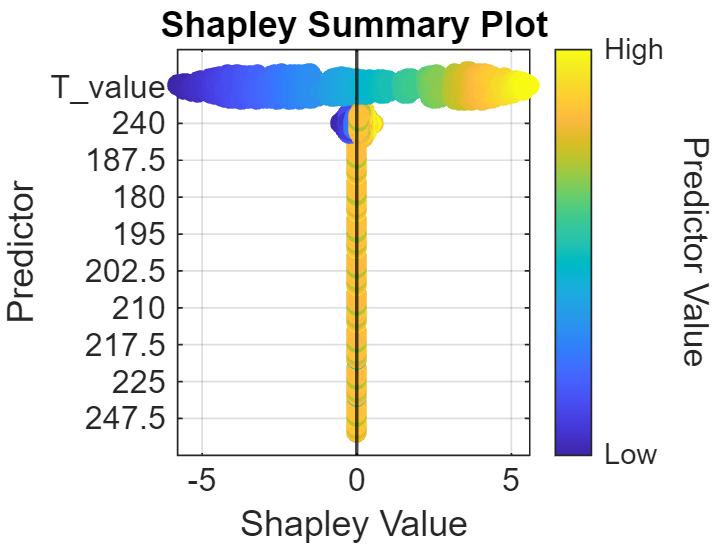

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"         1.5942e-14 
    "187.5"       1.5955e-14 
    "195"         1.4104e-14 
    "202.5"       1.4099e-14 
    "210"         1.4095e-14 
    "217.5"       1.4087e-14 
    "225"         1.3885e-14 
    "232.5"       1.3733e-14 
    "240"            0.20536 
    "247.5"       1.3747e-14 
    "255"         1.3731e-14 
    "262.5"       1.3693e-14 
    "270"         1.3694e-14 
    "T_value"         2.8113 


  Properties, Methods



    "2 senors, index: 4"    "2 senors, index: 9"



    "Positions: 202.5"    "Positions: 240"



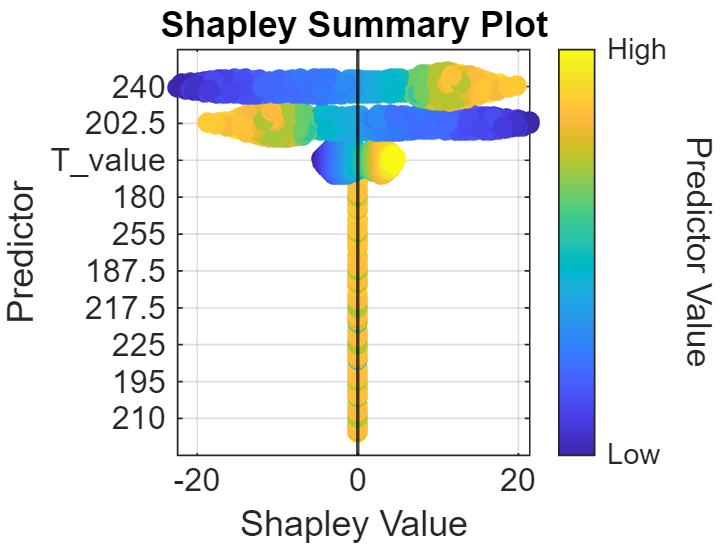

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"         9.2282e-14 
    "187.5"       8.7627e-14 
    "195"         8.3922e-14 
    "202.5"           9.1262 
    "210"         8.2832e-14 
    "217.5"       8.5988e-14 
    "225"         8.4792e-14 
    "232.5"       8.2674e-14 
    "240"             9.8519 
    "247.5"        8.114e-14 
    "255"         8.8945e-14 
    "262.5"       8.0054e-14 
    "270"         8.0232e-14 
    "T_value"         2.2192 


  Properties, Methods



    "3 senors, index: 1"    "3 senors, index: 4"    "3 senors, index: 8"



    "Positions: 180"    "Positions: 202.5"    "Positions: 232.5"



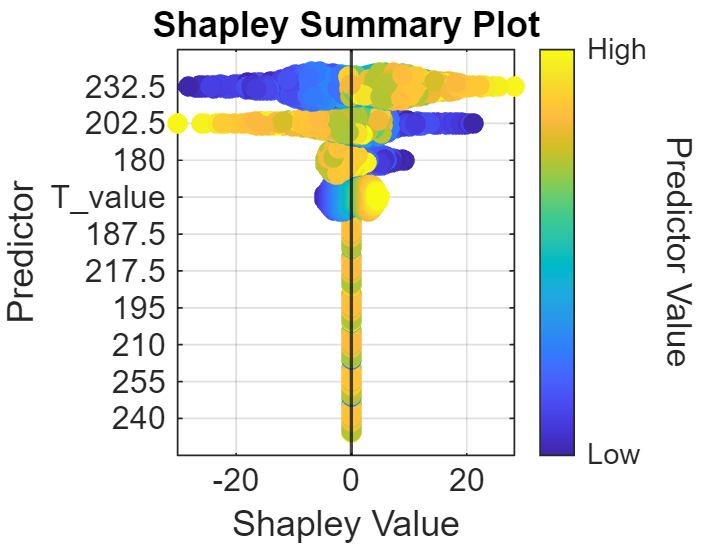

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"             2.7333 
    "187.5"       4.9313e-13 
    "195"         4.5475e-13 
    "202.5"           5.5237 
    "210"         4.5393e-13 
    "217.5"       4.5528e-13 
    "225"         4.4886e-13 
    "232.5"           8.5379 
    "240"         4.5068e-13 
    "247.5"       4.4458e-13 
    "255"         4.5131e-13 
    "262.5"       4.4387e-13 
    "270"         4.4404e-13 
    "T_value"         2.2588 


  Properties, Methods



    "4 senors, index: 1"    "4 senors, index: 4"    "4 senors, index: 8"    "4 senors, index: 9"



    "Positions: 180"    "Positions: 202.5"    "Positions: 232.5"    "Positions: 240"



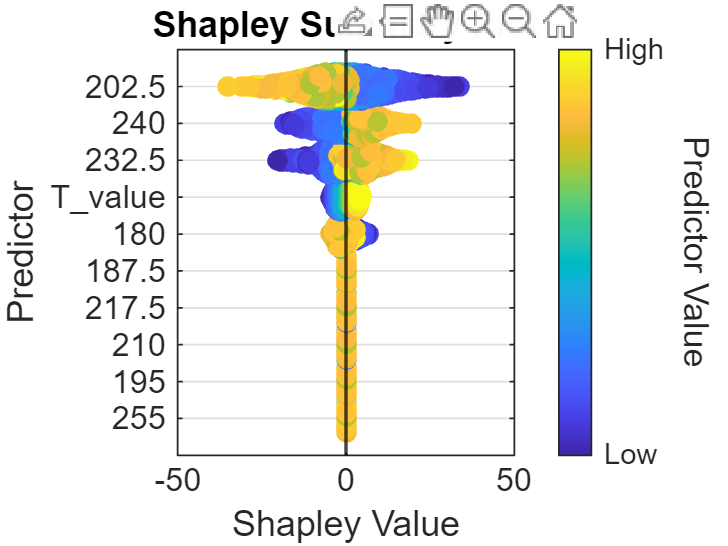

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"             2.0233 
    "187.5"       9.2384e-13 
    "195"         8.5641e-13 
    "202.5"           9.2795 
    "210"         8.5768e-13 
    "217.5"       8.5901e-13 
    "225"         8.4976e-13 
    "232.5"           5.9124 
    "240"             6.1896 
    "247.5"       8.4877e-13 
    "255"         8.5249e-13 
    "262.5"       8.4515e-13 
    "270"          8.457e-13 
    "T_value"          2.075 


  Properties, Methods



    "5 senors, index: 3"    "5 senors, index: 4"    "5 senors, index: 8"    "5 senors, index: 9"    "5 senors, index: 12"



    "Positions: 195"    "Positions: 202.5"    "Positions: 232.5"    "Positions: 240"    "Positions: 262.5"



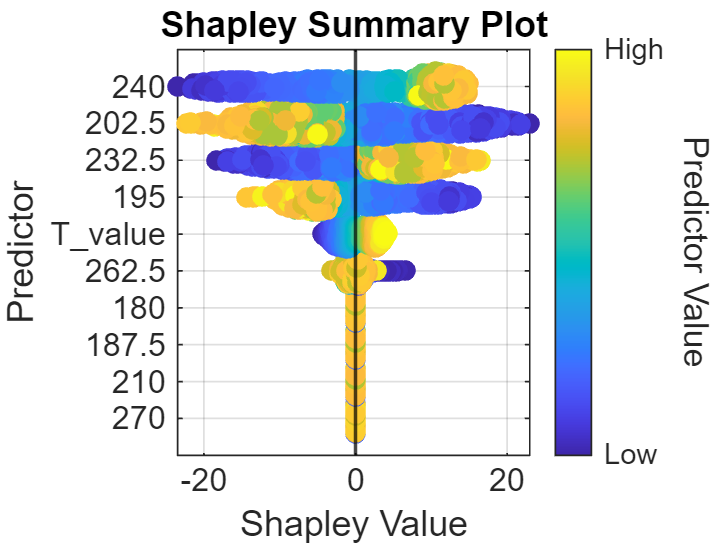

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"         5.6097e-13 
    "187.5"       5.6084e-13 
    "195"             6.1398 
    "202.5"           8.6774 
    "210"         5.3518e-13 
    "217.5"        5.325e-13 
    "225"         5.3119e-13 
    "232.5"            6.875 
    "240"             9.6972 
    "247.5"        5.318e-13 
    "255"          5.334e-13 
    "262.5"          0.94956 
    "270"         5.3342e-13 
    "T_value"         1.9247 


  Properties, Methods



    "6 senors, index: 3"    "6 senors, index: 4"    "6 senors, index: 5"    "6 senors, index: 8"    "6 senors, index: 9"    "6 senors, index: 12"



    "Positions: 195"    "Positions: 202.5"    "Positions: 210"    "Positions: 232.5"    "Positions: 240"    "Positions: 262.5"



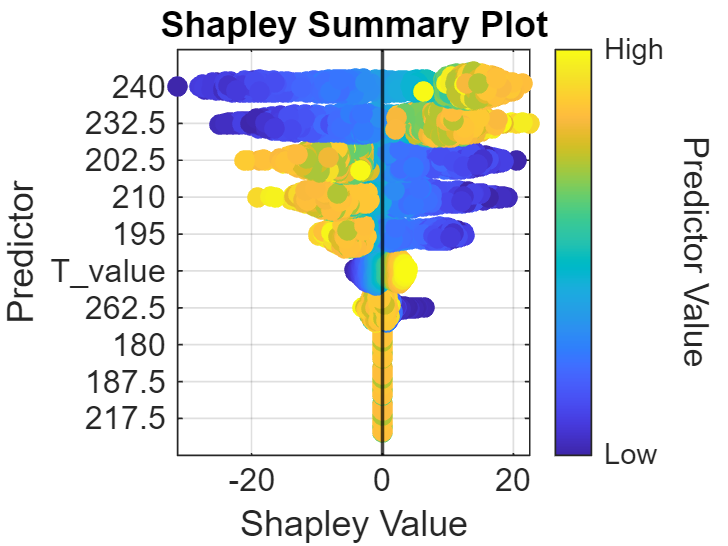

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"         8.5356e-13 
    "187.5"       8.5134e-13 
    "195"             5.0659 
    "202.5"           7.2613 
    "210"             6.6628 
    "217.5"       8.2403e-13 
    "225"         8.2198e-13 
    "232.5"            9.067 
    "240"             12.033 
    "247.5"       8.1633e-13 
    "255"          8.195e-13 
    "262.5"           1.1411 
    "270"         8.1862e-13 
    "T_value"          1.807 


  Properties, Methods



    "7 senors, index: 3"    "7 senors, index: 4"    "7 senors, index: 5"    "7 senors, index: 8"    "7 senors, index: 9"    "7 senors, index: 10"    "7 senors, index: 12"



    "Positions: 195"    "Positions: 202.5"    "Positions: 210"    "Positions: 232.5"    "Positions: 240"    "Positions: 247.5"    "Positions: 262.5"



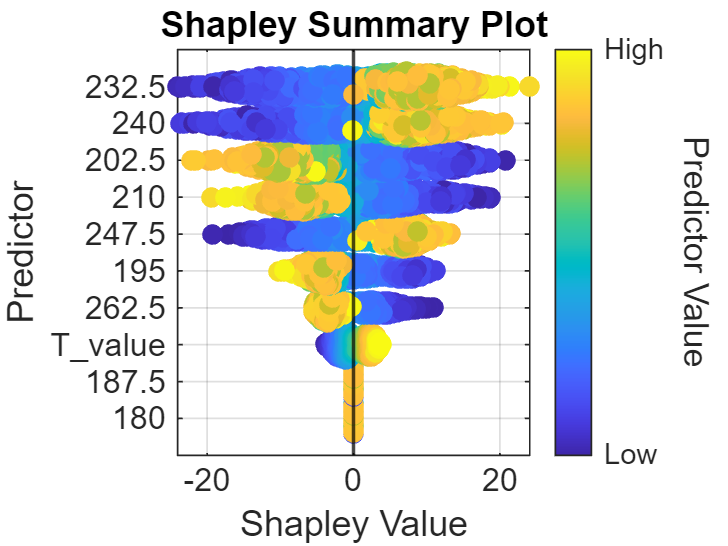

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"         8.6264e-13 
    "187.5"       8.6275e-13 
    "195"             4.3785 
    "202.5"           7.7492 
    "210"             6.7987 
    "217.5"       8.4888e-13 
    "225"         8.4989e-13 
    "232.5"           8.6779 
    "240"             8.3894 
    "247.5"           6.4486 
    "255"         8.5091e-13 
    "262.5"           3.4602 
    "270"          8.497e-13 
    "T_value"         1.7148 


  Properties, Methods



    "8 senors, index: 3"    "8 senors, index: 4"    "8 senors, index: 5"    "8 senors, index: 7"    "8 senors, index: 8"    "8 senors, index: 9"    "8 senors, index: 10"    "8 senors, index: 12"



    "Positions: 195"    "Positions: 202.5"    "Positions: 210"    "Positions: 225"    "Positions: 232.5"    "Positions: 240"    "Positions: 247.5"    "Positions: 262.5"



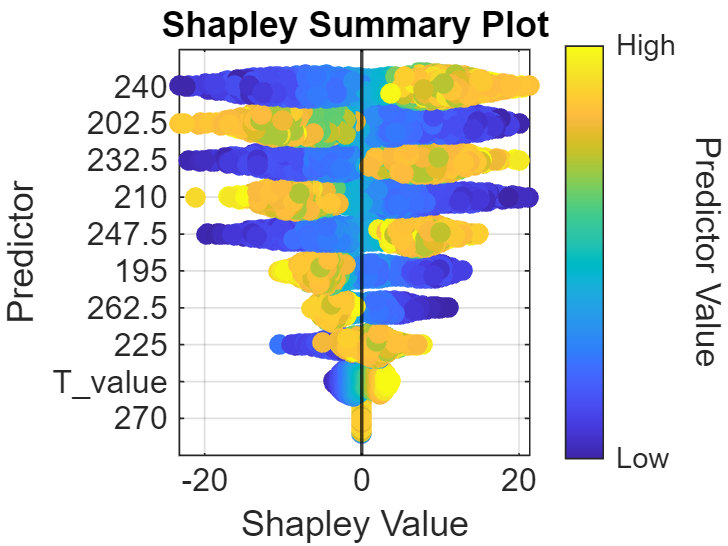

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"         1.0545e-12 
    "187.5"       1.0537e-12 
    "195"             5.0454 
    "202.5"           8.0645 
    "210"             7.4678 
    "217.5"       1.0517e-12 
    "225"             2.4081 
    "232.5"           7.7444 
    "240"             8.9398 
    "247.5"           6.6126 
    "255"         1.0542e-12 
    "262.5"           3.5654 
    "270"         1.0554e-12 
    "T_value"         1.6574 


  Properties, Methods



    "9 senors, index: 2"    "9 senors, index: 3"    "9 senors, index: 4"    "9 senors, index: 5"    "9 senors, index: 7"    "9 senors, index: 8"    "9 senors, index: 9"    "9 senors, index: 10"    "9 senors, index: 12"



    "Positions: 187.5"    "Positions: 195"    "Positions: 202.5"    "Positions: 210"    "Positions: 225"    "Positions: 232.5"    "Positions: 240"    "Positions: 247.5"    "Positions: 262.5"



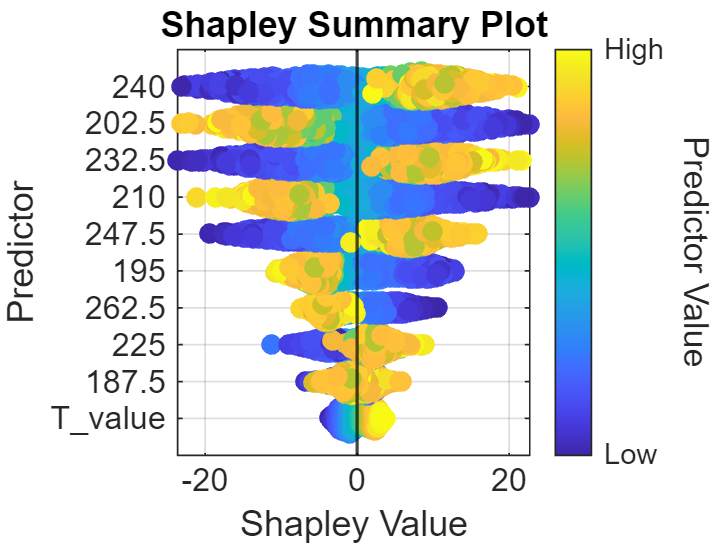

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"         1.3479e-12 
    "187.5"           1.6999 
    "195"              5.082 
    "202.5"           8.8318 
    "210"             7.7332 
    "217.5"        1.297e-12 
    "225"             3.1039 
    "232.5"           8.4237 
    "240"             8.8505 
    "247.5"           6.6858 
    "255"         1.3001e-12 
    "262.5"           3.7045 
    "270"         1.2965e-12 
    "T_value"         1.6107 


  Properties, Methods



    "10 senors, index: 1"    "10 senors, index: 2"    "10 senors, index: 3"    "10 senors, index: 4"    "10 senors, index: 5"    "10 senors, index: 7"    "10 senors, index: 8"    "10 senors, index: 9"    "10 senors, index: 10"    "10 senors, index: 12"



    "Positions: 180"    "Positions: 187.5"    "Positions: 195"    "Positions: 202.5"    "Positions: 210"    "Positions: 225"    "Positions: 232.5"    "Positions: 240"    "Positions: 247.5"    "Positions: 262.5"



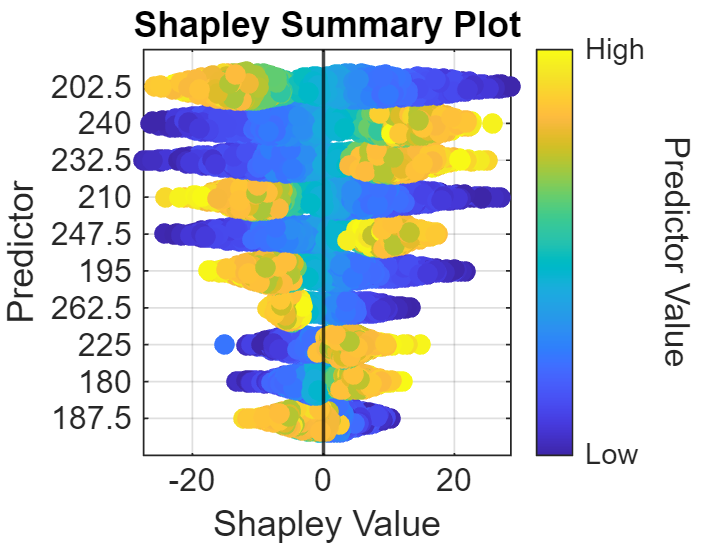

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"             3.8796 
    "187.5"            3.544 
    "195"              7.213 
    "202.5"           11.028 
    "210"             8.9075 
    "217.5"       1.6498e-12 
    "225"             4.0756 
    "232.5"           9.6658 
    "240"             10.902 
    "247.5"           8.4037 
    "255"         1.6485e-12 
    "262.5"           4.6838 
    "270"         1.6474e-12 
    "T_value"         1.4888 


  Properties, Methods



    "11 senors, index: 1"    "11 senors, index: 2"    "11 senors, index: 3"    "11 senors, index: 4"    "11 senors, index: 5"    "11 senors, index: 7"    "11 senors, index: 8"    "11 senors, index: 9"    "11 senors, index: 10"    "11 senors, index: 12"    "11 senors, index: 13"



    "Positions: 180"    "Positions: 187.5"    "Positions: 195"    "Positions: 202.5"    "Positions: 210"    "Positions: 225"    "Positions: 232.5"    "Positions: 240"    "Positions: 247.5"    "Positions: 262.5"    "Positions: 270"



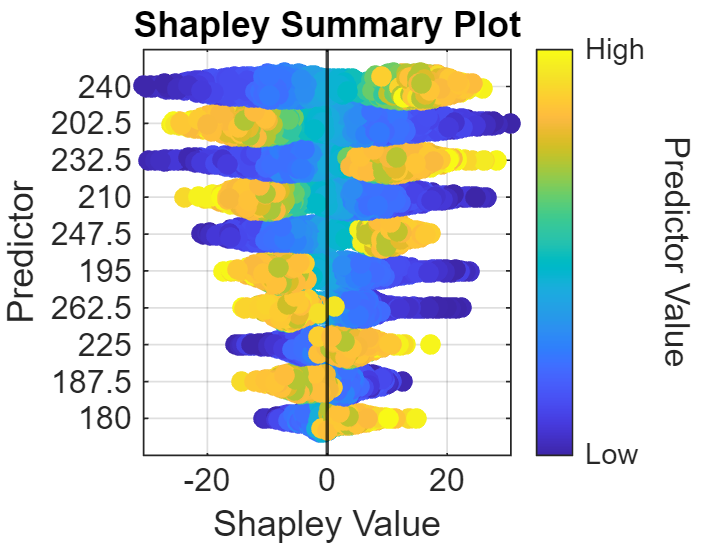

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"             3.1496 
    "187.5"             4.24 
    "195"              7.125 
    "202.5"           11.358 
    "210"              8.969 
    "217.5"       1.7312e-12 
    "225"             4.4414 
    "232.5"           9.9464 
    "240"             12.023 
    "247.5"           8.2318 
    "255"         1.7198e-12 
    "262.5"           5.9922 
    "270"             1.7174 
    "T_value"         1.4338 


  Properties, Methods



    "12 senors, index: 1"    "12 senors, index: 2"    "12 senors, index: 3"    "12 senors, index: 4"    "12 senors, index: 5"    "12 senors, index: 7"    "12 senors, index: 8"    "12 senors, index: 9"    "12 senors, index: 10"    "12 senors, index: 11"    "12 senors, index: 12"    "12 senors, index: 13"



    "Positions: 180"    "Positions: 187.5"    "Positions: 195"    "Positions: 202.5"    "Positions: 210"    "Positions: 225"    "Positions: 232.5"    "Positions: 240"    "Positions: 247.5"    "Positions: 255"    "Positions: 262.5"    "Positions: 270"



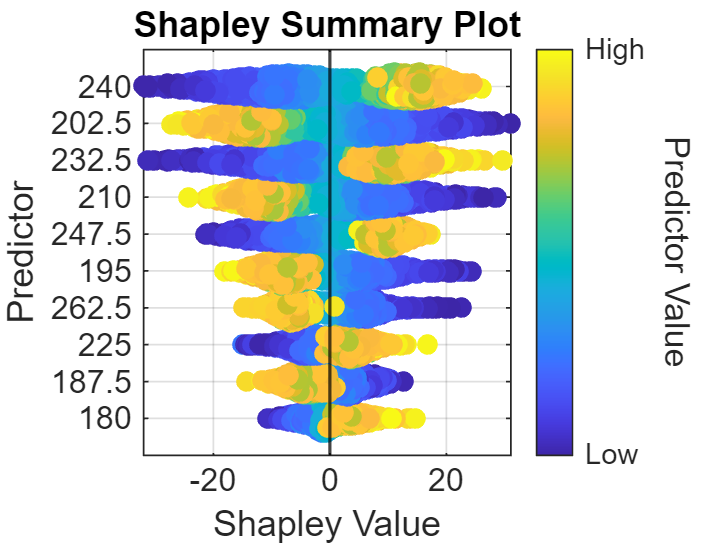

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"             3.3057 
    "187.5"           4.2328 
    "195"             7.2545 
    "202.5"           11.459 
    "210"             9.1107 
    "217.5"       1.9274e-12 
    "225"             4.3722 
    "232.5"           9.8722 
    "240"             12.104 
    "247.5"           8.2403 
    "255"             1.1976 
    "262.5"            6.213 
    "270"             1.6617 
    "T_value"         1.4227 


  Properties, Methods



    "13 senors, index: 1"    "13 senors, index: 2"    "13 senors, index: 3"    "13 senors, index: 4"    "13 senors, index: 5"    "13 senors, index: 6"    "13 senors, index: 7"    "13 senors, index: 8"    "13 senors, index: 9"    "13 senors, index: 10"    "13 senors, index: 11"    "13 senors, index: 12"    "13 senors, index: 13"



    "Positions: 180"    "Positions: 187.5"    "Positions: 195"    "Positions: 202.5"    "Positions: 210"    "Positions: 217.5"    "Positions: 225"    "Positions: 232.5"    "Positions: 240"    "Positions: 247.5"    "Positions: 255"    "Positions: 262.5"    "Positions: 270"



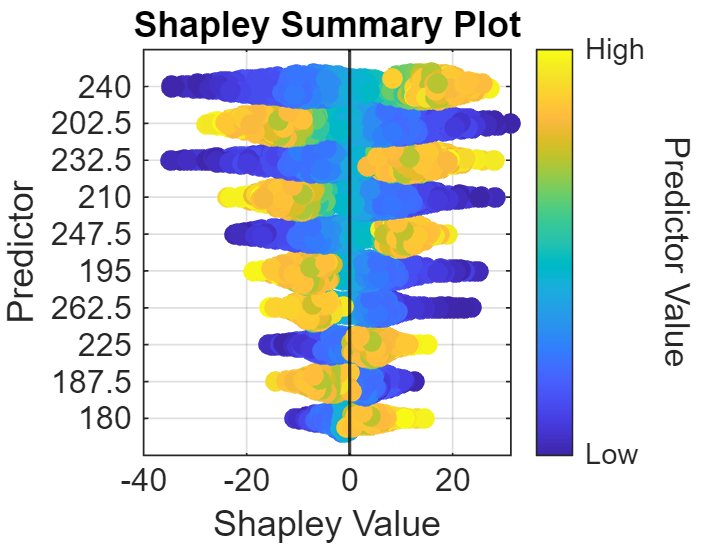

shapval = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"           3.3634   
    "187.5"         4.2916   
    "195"           7.4336   
    "202.5"         11.554   
    "210"           8.9844   
    "217.5"         2.0443   
    "225"           4.7932   
    "232.5"          10.71   
    "240"           12.848   
    "247.5"         8.4889   
    "255"           1.1603   
    "262.5"         6.3621   
    "270"           1.6118   
    "T_value"       1.3916   


  Properties, Methods



sensorpositions = {'180','187.5','195','202.5','210','217.5','225',...
    '232.5','240','247.5','255','262.5','270'};

for i = 1:13
    idx = bestSubset(i).combination;
    disp(i+" senors, index: "+idx)
    disp("Positions: "+sensorpositions(idx))
    shapval = compute_shap(bestSubset,i)
    shap_struct(i).shap_val = shapval;
end

Local Function (Compute Shapley Values)

function shap_val = compute_shap(bS_struct,sensor_num)
% input: bestSubset; output: shap_val & swarmchart
bestSubset = bS_struct;
Tp14_tbl = bestSubset(sensor_num).Tp_14_sorted_fitted;
predFcn = bestSubset(sensor_num).Tp_model.predictFcn;
idx = bestSubset(sensor_num).combination;

shap = shapley(predFcn,Tp14_tbl(:,1:end-1),UseParallel=true);

shap =             BlackboxModel: @(x)linearModelPredictFcn(predictorExtractionFcn(x))
              QueryPoints: []
           BlackboxFitted: []
            ShapleyValues: []
                        X: [1378×14 table]
    CategoricalPredictors: []
                   Method: "interventional-kernel"
                Intercept: 42.2131
               NumSubsets: 1024


shap_val = fit(shap,Tp14_tbl(:,1:end-1),UseParallel=true);

shap_val = shapley explainer with the following mean absolute Shapley values:

    Predictor    ShapleyValue
    _________    ____________

    "180"             9.9786 
    "187.5"            7.962 
    "195"             18.748 
    "202.5"            23.34 
    "210"             18.806 
    "217.5"       8.6772e-13 
    "225"             7.8707 
    "232.5"           20.238 
    "240"             24.734 
    "247.5"           16.227 
    "255"         8.6334e-13 
    "262.5"           7.2148 
    "270"         8.7485e-13 
    "T_value"     8.7996e-13 


  Properties, Methods



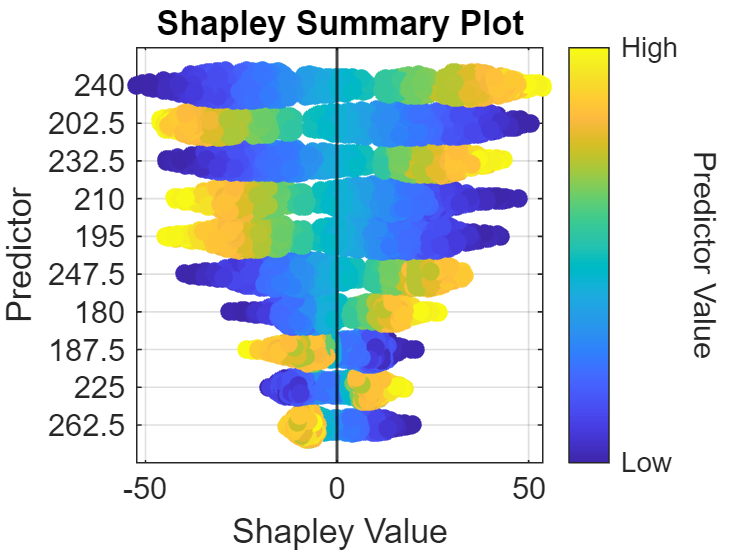

figure, swarmchart(shap_val)


end